# QN3: Optimal trapezoidal channel cross-section 

QN. An unlined trapezoidal irrigation channel must carry a design discharge of 12 m^3/s. Side slope is 1.5H:1V, Manning's n = 0.025 and bed slope is 0.0008. Cost per metre of channel is 30 per m^2 of excavated flow area plus 80 per m of wetted perimeter (lining/protection). Flow velocity must stay between 0.6 m/s (no silting) and 2.0 m/s (no scouring). Find the bed width b and depth y that minimize the cost per metre.

MATHEMATICAL MODEL Variables b (m), y (m) A = (b + z y) y , P = b + 2 y sqrt(1+z^2) , z = 1.5 Minimize C(b,y) = c1*A + c2*P Subject to Q_cap = (1/n) A^(5/3) P^(-2/3) S^(1/2) >= Q_req (Manning) 0.6 <= Q_req/A <= 2.0 (velocity) 0.5 <= b <= 20 , 0.3 <= y <= 5 Solver: fmincon (SQP algorithm).

clear; clc; close all;
if ~license('test','Optimization_Toolbox'), error('Optimization Toolbox is not installed/licensed.'); end

z = 1.5; n = 0.025; S = 0.0008; Qreq = 12;
c1 = 30; c2 = 80; Vmin = 0.6; Vmax = 2.0;

area = @(b,y) (b + z*y).*y;
perim = @(b,y) b + 2*y*sqrt(1+z^2);
cost = @(x) c1*area(x(1),x(2)) + c2*perim(x(1),x(2));
qcap = @(b,y) (1/n)*area(b,y).^(5/3).*perim(b,y).^(-2/3)*sqrt(S);

% constraints as anonymous functions (works in all MATLAB versions)
Ax   = @(x) (x(1) + z*x(2))*x(2);
Px   = @(x) x(1) + 2*x(2)*sqrt(1+z^2);
Qx   = @(x) (1/n)*Ax(x)^(5/3)*Px(x)^(-2/3)*sqrt(S);
nonl = @(x) deal([Qreq - Qx(x); Qreq/Ax(x) - Vmax; Vmin - Qreq/Ax(x)], []);

x0 = [5 1.6]; lb = [0.5 0.3]; ub = [20 5];
opts = optimoptions('fmincon','Algorithm','sqp','Display','none');
[xopt, fval, exitflag] = fmincon(cost, x0, [], [], [], [], lb, ub, ...
        nonl, opts);
if exitflag <= 0, error('No optimal solution found (exitflag = %d)', exitflag); end

b = xopt(1); y = xopt(2);
fprintf('Optimal bed width b = %.3f m\n', b);

Optimal bed width b = 1.320 m


fprintf('Optimal depth     y = %.3f m\n', y);

Optimal depth     y = 2.181 m


fprintf('Flow area A = %.3f m^2, wetted perimeter P = %.3f m\n', area(b,y), perim(b,y));

Flow area A = 10.012 m^2, wetted perimeter P = 9.183 m


fprintf('Capacity Q = %.3f m^3/s (required %.1f)\n', qcap(b,y), Qreq);

Capacity Q = 12.000 m^3/s (required 12.0)


fprintf('Velocity V = %.3f m/s\n', Qreq/area(b,y));

Velocity V = 1.199 m/s


fprintf('Minimum cost = %.2f per metre\n', fval);

Minimum cost = 1035.01 per metre


## PLOTS

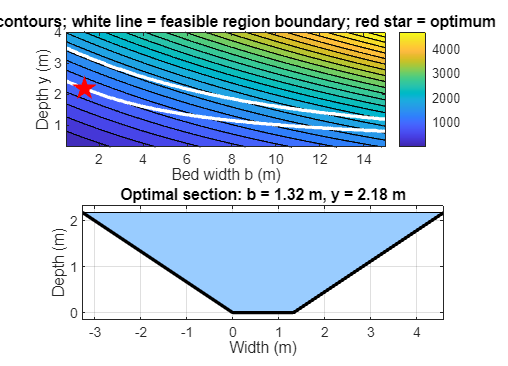

[B, Y] = meshgrid(linspace(0.5,15,200), linspace(0.3,4,200));
C = c1*area(B,Y) + c2*perim(B,Y);
Q = qcap(B,Y);
V = Qreq./area(B,Y);
feas = (Q >= Qreq) & (V >= Vmin) & (V <= Vmax);

figure('Position',[100 100 900 650]);
subplot(2,1,1);
contourf(B, Y, C, 25); colorbar; hold on;
contour(B, Y, double(feas), [0.5 0.5], 'w-', 'LineWidth', 2);
plot(b, y, 'rp', 'MarkerSize', 14, 'MarkerFaceColor','r');
xlabel('Bed width b (m)'); ylabel('Depth y (m)');
title('Cost contours; white line = feasible region boundary; red star = optimum');

subplot(2,1,2);
fill([0 b b+z*y -z*y], [0 0 y y], [0.6 0.8 1]); hold on;
plot([-z*y 0 b b+z*y], [y 0 0 y], 'k-', 'LineWidth', 2);
axis equal; grid on; xlabel('Width (m)'); ylabel('Depth (m)');
title(sprintf('Optimal section: b = %.2f m, y = %.2f m', b, y));
saveas(gcf,'problem3_plots.png');